close all; clearvars data x;
clear figure(4);
device = serialport("COM11", 9600)

device =   Serialport with properties:

                 Port: "COM11"
             BaudRate: 9600
    NumBytesAvailable: 49

  Show all properties, functions


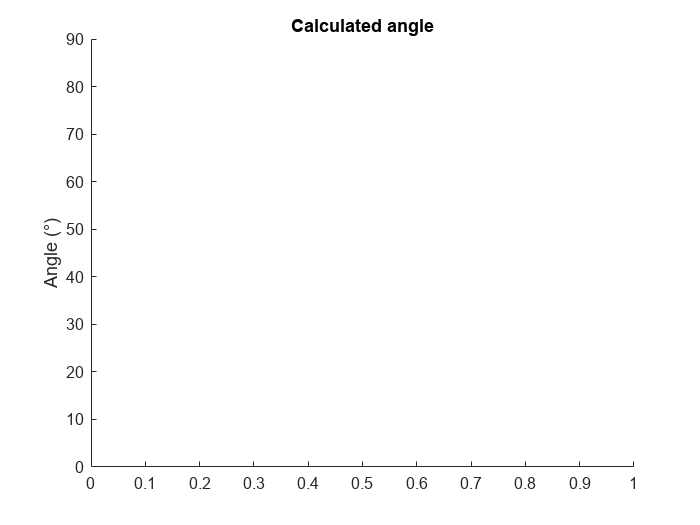

x =1;
figure(1);
hold on;
while 1
  data(x) = str2double(readline(device));
  plot(data,'-r')
  ylim([0,90])
ylabel("Angle (°)")
title("Calculated angle")
  x = x+1;
end